clear; clc;

% === Load airfoil data ===
data =[-5, -0.4, 0.03
0,  0.0,  0.02
5,  0.7,  0.025
10, 1.0,  0.035
12, 1.1,  0.045
15, 1.05, 0.06];  

% [alpha, CL, CD]
alpha_data = data(:,1);  % degrees
CL_data = data(:,2);
CD_data = data(:,3);

% === Inputs ===
Nb = 3;                   % Number of blades
R = 0.78;                 % Radius (m)
R_hub = 0.15 * R;
rho = 0.819;              % Air density (kg/m³)
V_inf = 36;               % Freestream speed (m/s)
RPM = 1460;
omega = RPM * 2*pi/60;
n_elements = 10;
mu = 1.78e-5;             % Air viscosity at 4 km (Pa·s)

% === Discretize blade ===
r = linspace(R_hub, R, n_elements);
dr = diff([r, R]);
c = zeros(1, n_elements);
theta = zeros(1, n_elements);
dT = zeros(1, n_elements);
dQ = zeros(1, n_elements);

for i = 1:n_elements
    % === Initial estimates ===
    a = 0.3;   % axial inflow factor
    tol = 1e-4;
    iter = 0;
    max_iter = 100;
    conv = false;
    
    while ~conv && iter < max_iter
        iter = iter + 1;
        
        % Flow components
        V_rot = omega * r(i);
        V_axial = V_inf * (1 - a);
        V_rel = sqrt(V_axial^2 + V_rot^2);
        phi = atan2(V_axial, V_rot);  % radians
        
        alpha = rad2deg(phi);  % approximate pitch angle
        
        % Interpolate CL, CD
        CL = interp1(alpha_data, CL_data, alpha, 'linear', 'extrap');
        CD = interp1(alpha_data, CD_data, alpha, 'linear', 'extrap');
        
        % Tip loss factor (Prandtl)
        F = (2/pi)*acos(exp(-(Nb/2)*(R - r(i))/(r(i)*sin(phi))));
        F = max(F, 1e-4);  % avoid divide by 0
        
        % Chord from momentum theory (ideal case)
        sigma = 0.08;  % blade solidity estimate
        c(i) = (8 * pi * r(i) * sin(phi) * cos(phi)) / (Nb * CL); % initial guess
        
        % Reynolds number
        Re = rho * V_rel * c(i) / mu;
        
        % Adjust efficiency if Re < 50k
        eta_Re = min(1, Re / 5e4);
        CL = CL * eta_Re;
        CD = CD + (1 - eta_Re) * 0.02;  % crude drag penalty
        
        % Thrust and torque
        q = 0.5 * rho * V_rel^2;
        L = q * c(i) * CL * dr(i);
        D = q * c(i) * CD * dr(i);
        
        dT_new = Nb * (L * cos(phi) - D * sin(phi));
        dQ_new = Nb * r(i) * (L * sin(phi) + D * cos(phi));
        
        % Update a (Glauert approximation)
        CT = dT_new / (rho * V_inf^2 * 2 * pi * r(i) * dr(i));
        anew = 1 / ( (4 * F * sin(phi)^2) / (sigma * CL * cos(phi)) + 1 );
        
        if abs(anew - a) < tol
            conv = true;
        end
        a = 0.75 * a + 0.25 * anew;  % under-relax
    end
    
    theta(i) = rad2deg(phi + deg2rad(6));  % design AoA of 6°
    dT(i) = dT_new;
    dQ(i) = dQ_new;
end

% === Totals ===
T_total = sum(dT);
Q_total = sum(dQ);
P_total = Q_total * omega / 1000;  % kW

% === Output ===
fprintf('--- Enhanced BEMT Results ---\n');

--- Enhanced BEMT Results ---


fprintf('Total Thrust: %.2f N\n', T_total);

Total Thrust: 5053.59 N


fprintf('Total Torque: %.2f Nm\n', Q_total);

Total Torque: 1278.27 Nm


fprintf('Power Required: %.2f kW\n', P_total);

Power Required: 195.44 kW


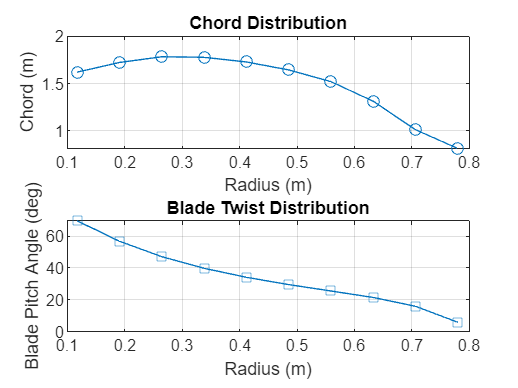


% === Plots ===
figure;
subplot(2,1,1);
plot(r, c, '-o'); grid on;
xlabel('Radius (m)'); ylabel('Chord (m)');
title('Chord Distribution');

subplot(2,1,2);
plot(r, theta, '-s'); grid on;
xlabel('Radius (m)'); ylabel('Blade Pitch Angle (deg)');
title('Blade Twist Distribution');